% 设置中文字体
set(groot, 'DefaultTextFontName', 'Kaiti');
set(groot, 'DefaultAxesFontName', 'Kaiti');

fprintf('============================================================\n');

fprintf('案例1：咖啡冷却温度预测\n');

案例1：咖啡冷却温度预测


fprintf('基于牛顿冷却定律的非线性回归分析\n');

基于牛顿冷却定律的非线性回归分析


fprintf('============================================================\n');

% 1. 数据生成与探索
function [time_data, measured_temp, true_temp, true_params] = generate_coffee_data(n_points, noise_level)
    rng(42); % 设置随机种子
    
    % 实际测量的时间点（分钟）
    time_data = linspace(0, 60, n_points);
    
    % 真实的冷却规律：T = T_room + (T_initial - T_room) * exp(-k*t)
    T_room = 22;    % 室温
    T_initial = 95; % 初始温度
    k = 0.045;      % 冷却系数
    
    % 理论温度
    true_temp = T_room + (T_initial - T_room) * exp(-k * time_data);
    
    % 添加测量误差
    noise = noise_level * randn(size(time_data));
    measured_temp = true_temp + noise;
    
    true_params = [T_room, T_initial, k];
end

% 生成数据
[n_points, noise_level] = deal(25, 1.2);
[time_data, measured_temp, true_temp, true_params] = generate_coffee_data(n_points, noise_level);

% 创建数据表格
df = table(time_data', measured_temp', true_temp', (measured_temp - true_temp)', ...
    'VariableNames', {'时间_分钟', '测量温度_°C', '真实温度_°C', '温度差'});

% 数据预览
fprintf('\n 咖啡冷却实验数据预览：\n');


 咖啡冷却实验数据预览：


disp(df(1:10, :));

    时间_分钟    测量温度_°C    真实温度_°C     温度差  
    ________    __________    __________    ________

         0        94.354            95      -0.64589
       2.5        88.273        87.233        1.0407
         5        81.463        80.292        1.1712
       7.5        74.494        74.089       0.40487
        10        67.352        68.547       -1.1953
      12.5        62.966        63.594      -0.62786
        15        57.611        59.168       -1.5569
      17.5        56.314        55.214        1.1009
        20        51.892         51.68       0.21192
      22.5        49.428        48.522       0.90622




% 数据统计信息
fprintf('\n 数据统计信息：\n');


 数据统计信息：


fprintf('测量时间范围: %.1f - %.1f 分钟\n', min(time_data), max(time_data));

测量时间范围: 0.0 - 60.0 分钟


fprintf('温度范围: %.1f - %.1f °C\n', min(measured_temp), max(measured_temp));

温度范围: 27.3 - 94.4 °C


fprintf('平均测量误差: %.2f °C\n', mean(abs(df.("温度差"))));

平均测量误差: 0.85 °C


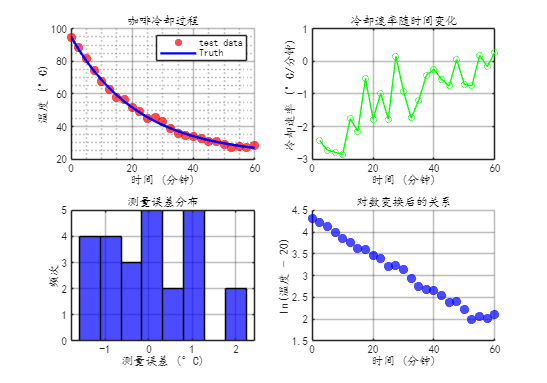

% 2. 数据可视化
fig = figure('Position', [100, 100, 1000, 700]);
subplot(2, 2, 1);

% 原始数据散点图
scatter(time_data, measured_temp, 60, 'red', 'filled', 'MarkerFaceAlpha', 0.7);
hold on;
plot(time_data, true_temp, 'blue', 'LineWidth', 2);
xlabel('时间 (分钟)');
ylabel('温度 (°C)');
title('咖啡冷却过程');
legend('test data', 'Truth');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3);

% 温度随时间变化率
subplot(2, 2, 2);
temp_diff = diff(measured_temp);
time_diff = diff(time_data);
cooling_rate = temp_diff ./ time_diff;

plot(time_data(2:end), cooling_rate, 'o-', 'Color', 'green', 'MarkerSize', 5);
xlabel('时间 (分钟)');
ylabel('冷却速率 (°C/分钟)');
title('冷却速率随时间变化');
grid on;
set(gca, 'GridAlpha', 0.3);

% 测量误差分布
subplot(2, 2, 3);
histogram(df.('温度差'), 8, 'FaceColor', 'blue', 'FaceAlpha', 0.7, 'EdgeColor', 'black');  % 修正：使用df.('温度差')
xlabel('测量误差 (°C)');
ylabel('频次');
title('测量误差分布');
grid on;
set(gca, 'GridAlpha', 0.3);

% 温度vs时间的对数关系
subplot(2, 2, 4);
scatter(time_data, log(measured_temp - 20), 60, 'blue', 'filled', 'MarkerFaceAlpha', 0.7);
xlabel('时间 (分钟)');
ylabel('ln(温度 - 20)');
title('对数变换后的关系');
grid on;
set(gca, 'GridAlpha', 0.3);

hold off;

% 3. 定义非线性回归模型
function T = newton_cooling_model(t, params)
    % 牛顿冷却定律模型
    % T = T_room + T_diff * exp(-k * t)
    T_room = params(1);
    T_diff = params(2);
    k = params(3);
    T = T_room + T_diff * exp(-k * t);
end

function T = exponential_decay_model(t, params)
    % 通用指数衰减模型
    % T = a + b * exp(-c * t)
    a = params(1);
    b = params(2);
    c = params(3);
    T = a + b * exp(-c * t);
end

% 4. 参数估计 - 多种方法比较
fprintf('\n 模型拟合与参数估计\n');


 模型拟合与参数估计


fprintf('----------------------------------------\n');

----------------------------------------



% 方法1：直接使用牛顿冷却定律
fprintf('方法1：牛顿冷却定律拟合\n');

方法1：牛顿冷却定律拟合



% 智能初值设定
T_room_init = min(measured_temp);  % 最低温度作为室温估计
T_diff_init = max(measured_temp) - T_room_init;  % 初始温度差
k_init = 0.05;  % 经验值

initial_guess_1 = [T_room_init, T_diff_init, k_init];
fprintf('初始猜测值: T_room=%.1f, T_diff=%.1f, k=%.3f\n', T_room_init, T_diff_init, k_init);

初始猜测值: T_room=27.3, T_diff=67.0, k=0.050



try
    options = optimoptions('lsqcurvefit', ...
            'MaxFunctionEvaluations', 10000, ...
            'Display', 'off');
    popt_1 = lsqcurvefit(@(params, t) newton_cooling_model(t, params), ...
        initial_guess_1, time_data, measured_temp, [], [], ...
        options);
    
    % 预测
    y_pred_1 = newton_cooling_model(time_data, popt_1);
    
    % 计算评估指标
    r2_1 = 1 - sum((measured_temp - y_pred_1).^2) / sum((measured_temp - mean(measured_temp)).^2);
    rmse_1 = sqrt(mean((measured_temp - y_pred_1).^2));
    mae_1 = mean(abs(measured_temp - y_pred_1));
    
    fprintf('拟合参数: T_room=%.2f°C, T_diff=%.2f°C, k=%.4f\n', popt_1(1), popt_1(2), popt_1(3));
    fprintf('评估指标: R²=%.4f, RMSE=%.2f°C, MAE=%.2f°C\n', r2_1, rmse_1, mae_1);
    
catch e
    fprintf('拟合失败: %s\n', e.message);
end

拟合参数: T_room=21.53°C, T_diff=73.50°C, k=0.0443


评估指标: R²=0.9973, RMSE=1.03°C, MAE=0.83°C


% 方法2：通用指数衰减模型
fprintf('\n方法2：通用指数衰减模型拟合\n');


方法2：通用指数衰减模型拟合



initial_guess_2 = [T_room_init, T_diff_init, k_init];

try
    options = optimoptions('lsqcurvefit', ...
            'MaxFunctionEvaluations', 10000, ...
            'Display', 'off');
    popt_2 = lsqcurvefit(@(params, t) exponential_decay_model(t, params), ...
        initial_guess_2, time_data, measured_temp, [], [], ...
        options);
    
    y_pred_2 = exponential_decay_model(time_data, popt_2);
    
    r2_2 = 1 - sum((measured_temp - y_pred_2).^2) / sum((measured_temp - mean(measured_temp)).^2);
    rmse_2 = sqrt(mean((measured_temp - y_pred_2).^2));
    mae_2 = mean(abs(measured_temp - y_pred_2));
    
    fprintf('拟合参数: a=%.2f, b=%.2f, c=%.4f\n', popt_2(1), popt_2(2), popt_2(3));
    fprintf('评估指标: R²=%.4f, RMSE=%.2f°C, MAE=%.2f°C\n', r2_2, rmse_2, mae_2);
    
catch e
    fprintf('拟合失败: %s\n', e.message);
end

拟合参数: a=21.53, b=73.50, c=0.0443


评估指标: R²=0.9973, RMSE=1.03°C, MAE=0.83°C
